clc; clear;

df = 0.08; rf = df/2;
d_kap = 0.015; rk = d_kap/2;
hf = 0.3;

d_tud = 10e-3;
Atud = (d_tud/2)^2*pi;

Vol = 1.5e-3;

Vv = 0.75e-3;

M = 0.1;

P0 = 5;


g = 9.81;
p2 = P0;


z2 = 3*Vv/(pi*(rf^2+rk^2+rf*rk))

z2 = 0.3661



rho_a = 1.246; % at 10 C
rho_v = 1000;

v1 = sqrt(2*(p2/rho_a + g*z2))

v1 = 3.8998


mdot = v1*rho_v*Atud

mdot = 0.3063

Vv = 0.1e-3:0.01e-3:1.5e-3;

z2 = 3*Vv./(pi*(rf^2+rk^2+rf*rk));
v1 = sqrt(2*(p2/rho_a + g.*z2));

mdot = v1*rho_v*Atud;

mv = Vv*rho_v;
mf = M + mv;

t = mv./mdot;

% syms t mf v1 m_dot

int1 = v1./mdot .* (mf - mdot.*t).*log(mf-mdot.*t) - (mf-mdot.*t) - mf.*log(mf) + mf;
int2 = g*1/2.*t.^2;
int3 = v1.*log(mf).*t;



h_int = int1+int2+int3;


% for i = 1:length(t_slut)
% 
%     % test(:,i) = subs(h_int, [t, mf, v1, mdot], [t_slut(i), mf1(i), v11(i), mdot1(i)]);
%     h1 = subs(int1, [v1, m_dot, mf, t], [v11(i), mdot1(i), mf1(i), t_slut(i)]);
% 
% end
% 
% length(int1)
% length(int2)
% length(int3)


clc; clear;

hf = 0.3;
mf = 0.1; % flaskemasse
Vf = 1.5e-3; % Flaske volumen
d_tud = 10e-3;
Atud = (d_tud/2)^2*pi;

P0 = 5e5; % Starttryk
Patm = 1e5;
gamma = 1.4; % cp/cv luft
rho_v = 1000;
rho_a = 1.246;
g = 9.81;

V = 1.5e-3; % Flaske volumen


% Arbejdsligning
flin = 0:0.001:1;

K = @(f) P0.*(1 - f).^gamma.*V.^gamma; % K konstant

W = @(f) K(f).*V.^(-gamma+1)/(-gamma+1) .* (1 - (1 - f).^(-gamma+1)); % Arbejde udført af gas

M_vand = @(f) rho_v*Vf.*f;
M0 = mf + M_vand(flin); % Total masse

W_mass = W(flin)./(mf + M_vand(flin));

% Initial velocity
v1 = @(f) sqrt(2*(P0/rho_v + g*hf.*f))

v1 = function_handle with value:
    @(f)sqrt(2*(P0/rho_v+g*hf.*f))



% Air Blast
Wb = @(f) P0*V/(-gamma+1) * ((1-f).^(-gamma+1)*(P0/Patm)^(1/gamma-1)-1)

Wb = function_handle with value:
    @(f)P0*V/(-gamma+1)*((1-f).^(-gamma+1)*(P0/Patm)^(1/gamma-1)-1)


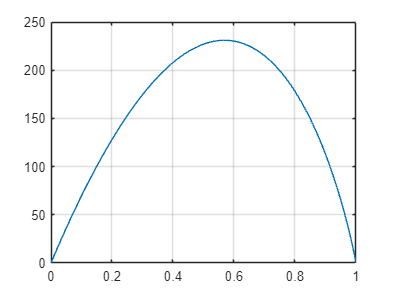

M_air = @(f) rho_a*Vf.*f;
M0_air = mf + M_air(flin); % Total masse



figure
plot(flin, W(flin))
grid

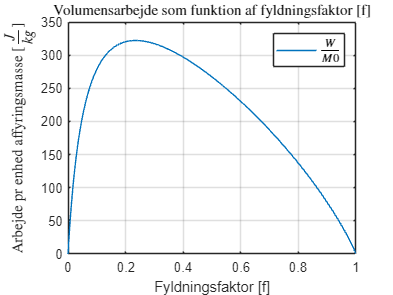


figure

plot(flin, W_mass,"DisplayName","$\frac{W}{M0}$")
title("Volumensarbejde som funktion af fyldningsfaktor [f]","Interpreter","latex")
xlabel("Fyldningsfaktor [f]")
ylabel("Arbejde pr enhed affyringsmasse [$\frac{J}{kg}$]","Interpreter","latex")
legend("Location","northeast","Interpreter","latex")
grid

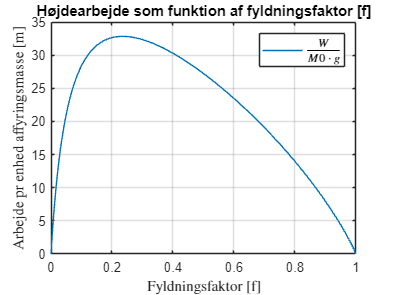


figure

plot(flin, W_mass/g,"DisplayName","$\frac{W}{M0\cdot g}$")
title("Højdearbejde som funktion af fyldningsfaktor [f]")
xlabel("Fyldningsfaktor [f]","Interpreter","latex")
ylabel("Arbejde pr enhed affyringsmasse [m]","Interpreter","latex")
legend("Location","northeast","Interpreter","latex")
grid







[MaxH, MaxHInd]=max(W_mass/g);

% flin(MaxHInd) * Vf * rho_v



f_max = flin(MaxHInd)*1.5

f_max = 0.3525




v1_max = sqrt(2*(P0/rho_v + g*hf*f_max))

v1_max = 31.6556




m_vand = V*f_max*rho_v;

mdot = v1_max*rho_v*Atud

mdot = 2.4862


t_max = m_vand/mdot

t_max = 0.2127


mf = 0.1 + m_vand

mf = 0.6288


tlin = 0:0.01:20;

v_raket = -v1_max*log((mf - mdot.*t_max)/mf) - g.*t_max

v_raket = 56.1145


a_raket = v1_max*(mf/(mf - mdot*t_max))*mdot-g

a_raket = 485.0337

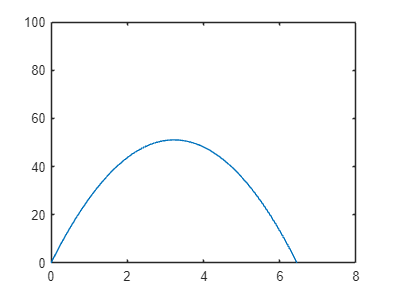



Sted_func = -1/2*g*tlin.^2 + v1_max*tlin;
v_func = -g*tlin + v1_max;

figure
plot(tlin, Sted_func)
ylim([0,100])

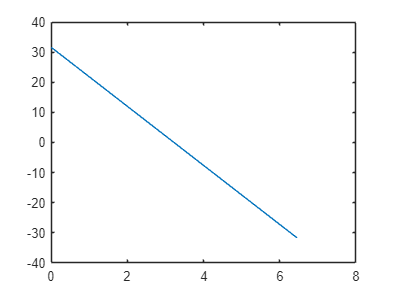


figure
plot(tlin(Sted_func>0), v_func(Sted_func>0))



W_mass(MaxHInd)

ans = 322.0947

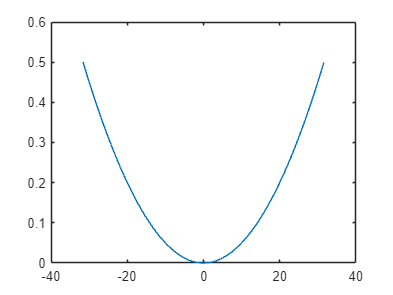



Cd = 0.16;
df = 0.08;
Ap = (df/2)^2*pi;

Fd = Cd*Ap*(rho_a*v_func.^2/2);

plot(v_func(Sted_func>0), Fd(Sted_func>0))

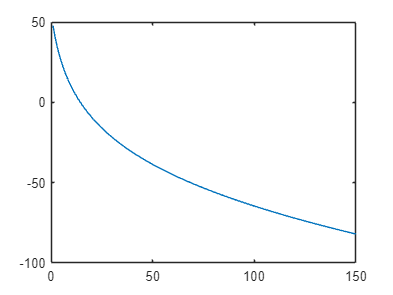





tlin = 0:0.01:20;

delta_m = m_vand - mdot.*tlin;


for i = 1:length(tlin)

    if delta_m < 0
        delta_m(i) = 0
    end

    v_raket(i) = -v1_max*log((mf - delta_m(i))/mf) - g.*tlin(i);

end


figure
plot(v_raket(1:150))

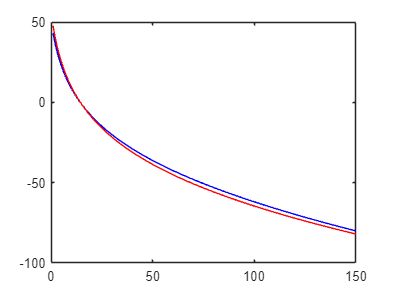






% Velocity with drag
Cd = 2.5;
Ap = Ap;
h_max = W_mass(MaxHInd)/g;

tlin = 0:0.01:20;

delta_m = m_vand - mdot.*tlin;


for i = 1:length(tlin)

    if delta_m < 0
        delta_m(i) = 0
    end

    v_raket_drag(i) = -v1_max*log((mf - delta_m(i))/mf) - g.*tlin(i) + Cd*Ap*(rho_a*v_func(i)^2/2)/mdot*log((mf-delta_m(i))/(mf));

end

figure
plot(v_raket_drag(1:150), "Color","b")
hold on
plot(v_raket(1:150), "Color","r")
hold off







v_func

v_func =    31.6446   31.5465   31.4484   31.3503   31.2522   31.1541   31.0560   30.9579   30.8598   30.7617   30.6636   30.5655   30.4674   30.3693   30.2712   30.1731   30.0750   29.9769   29.8788   29.7807   29.6826   29.5845   29.4864   29.3883   29.2902   29.1921   29.0940   28.9959   28.8978   28.7997   28.7016   28.6035   28.5054   28.4073   28.3092   28.2111   28.1130   28.0149   27.9168   27.8187   27.7206   27.6225   27.5244   27.4263   27.3282   27.2301   27.1320   27.0339   26.9358   26.8377
